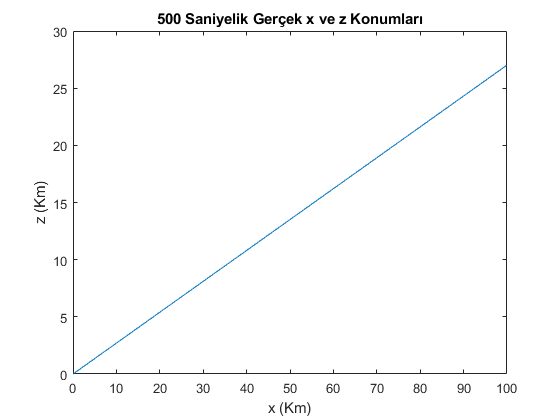

n=12;
v=195+n; %m/s
y0= 6355000; %m yükseklik-sabit
x0=0;
z0=0;
t_delta=1;
gama=(15+n/100)*pi/180;
adim=500;
x=x0:v*t_delta*cos(gama):v*t_delta*cos(gama)*adim;
z=z0:v*t_delta*sin(gama):v*t_delta*sin(gama)*adim;
y=zeros(1,adim+1)+3000;

figure(1)
h1=plot(x/1000,z/1000);
title('500 Saniyelik Gerçek x ve z Konumları');
xlabel('x (Km)');
ylabel('z (Km)');

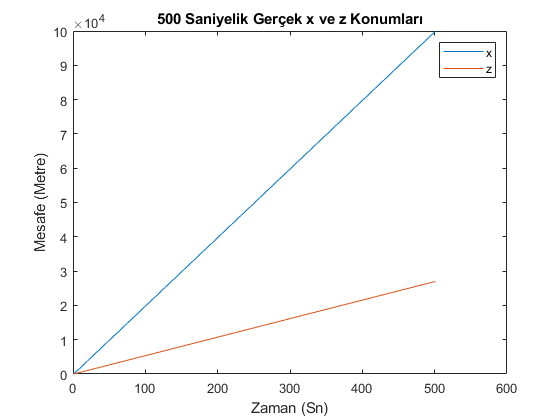


mesafe=zeros(1,4);
mesafe(1)=sqrt((z(end)-z(1))^2 + (x(end)-x(1))^2);

figure(5)
plot(x)
hold on
plot(z)
title('500 Saniyelik Gerçek x ve z Konumları');
xlabel("Zaman (Sn)")
ylabel("Mesafe (Metre)")
legend("x","z")

50 saniye sonunda 103500 metre yol katedilmiştir.

m1=(z(100)-z(99))/(x(100)-x(99));
m2=-1/m1;

st3=[  95190  ,-153700 , 30];
st1=[ 172200  , 136200 , 650];
st2=[-117400 , 58000  , 230];

st4=[0 0 0];


%Her bir istasyon ile uçak arasında olan mesafe
D1=sqrt( (st1(1)-x).^2 + (st1(2)-z).^2 + (st1(3)-y).^2 );
D2=sqrt( (st2(1)-x).^2 + (st2(2)-z).^2 + (st2(3)-y).^2 );
D3=sqrt( (st3(1)-x).^2 + (st3(2)-z).^2 + (st3(3)-y).^2 );
D4=sqrt( (st4(1)-x).^2 + (st4(2)-z).^2 + (st4(3)-y).^2 );

%Her bir istasyonun 0,0,0 noktasına olan mesafesi
l1 = sqrt(st1(1)^2 + st1(2)^2 + st1(3)^2 );
l2 = sqrt(st2(1)^2 + st2(2)^2 + st2(3)^2 );
l3 = sqrt(st3(1)^2 + st3(2)^2 + st3(3)^2 );
l4 = sqrt(st4(1)^2 + st4(2)^2 + st4(3)^2 );


%c1 = [St1(1)-St2(1), St1(2)-St2(2), St1(3)-St2(3)]
%c2 = [St1(1)-St3(1), St1(2)-St3(2), St1(3)-St3(3)]
%c3 = [St2(1)-St3(1), St2(2)-St3(2), St2(3)-St3(3)]





err

sigma_D=10; %metre
bias=10+n; % bias
% D Uçağa kadar olan mesafe
% Delta_D = Uçaktan iki çeşitli antene kadar olan mesafeler farkı
% Uçaktan iki çeşitli antene kadar olan mesafeler toplamı
% Belirli antene göre açıların doğrultman kosinüsleri
% Uçağın alfa:azimut ve beta: konum açılarını
% Kayıt olan parametrelerin değişme hızleri

DZ1 = D1 + bias + sigma_D*randn(1,501);
DZ2 = D2 + bias + sigma_D*randn(1,501);
DZ3 = D3 + bias + sigma_D*randn(1,501);
DZ4 = D4 + bias + sigma_D*randn(1,501);

c1=0.5* (DZ2.^2 - DZ1.^2 + l1^2 - l2^2);
c2=0.5* (DZ3.^2 - DZ1.^2 + l1^2 - l3^2);
c3=0.5* (DZ3.^2 - DZ2.^2 + l2^2 - l3^2);

e1=( c1.*(st2(2)-st3(2)) - c3.*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1)).*(st2(2) -st3(2)) - (st2(1)-st3(1)).*( st1(2)-st2(2))   );

e2=( c1.*(st1(1)-st3(1)) - c2.*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1)).*(st1(2) -st2(2)) - (st1(1)-st2(1)).*( st1(2)-st3(2))   );

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


a= ( (st1(3)-st2(3))*(st2(2)-st3(2)) - (st2(3)-st3(3))*(st1(2)-st2(2)) ) / ( (st1(1)-st2(1))*(st2(2)-st3(2)) - (st2(1)-st3(1))*(st1(2)-st2(2)) );

b= ( (st1(3)-st2(3))*(st1(1)-st3(1)) - (st1(3)-st3(3))*(st1(1)-st2(1)) ) / ( (st1(1)-st3(1))*(st1(2)-st2(2)) - (st1(1)-st2(1))*(st1(2)-st3(2)) );

p_a=ones(1,501)*(a^2 + b^2 + 1) ;
p_b=2*( st1(1)*a - st1(3) + st1(2)*b - a.*e1 - b.*e2) ;
p_c= -1*(DZ1.^2 - l1^2 - e1.^2 + 2*st1(1).*e1 - e2.^2 + 2*st1(2).*e2) ;  

polynom=[p_a',p_b', p_c'];



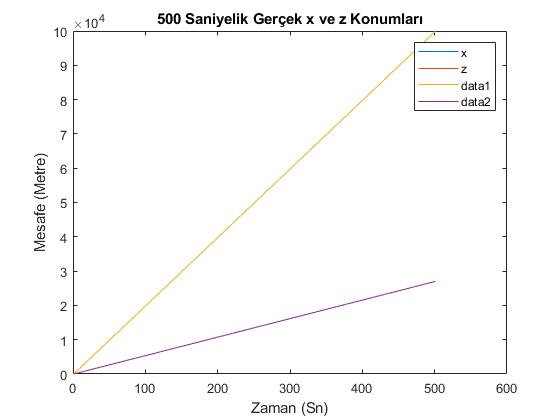

kokler=[-polynom(:,2) + sqrt(polynom(:,2).^2-4*polynom(:,1).*polynom(:,3)), -polynom(:,2) - sqrt(polynom(:,2).^2-4*polynom(:,1).*polynom(:,3))  ]/2;
y1_1=(-p_b + sqrt(p_b.^2-4*p_a.*p_c))./(2*p_a);
y1_2=(-p_b - sqrt(p_b.^2-4*p_a.*p_c))./(2*p_a);

x1_1 = e1-a.*y1_1;
z1_1=e2-b.*y1_1;

x1_2 = e1-a.*y1_2;
z1_2=e2-b.*y1_2;


figure(2)
plot(y)
hold on
plot(y1_1)
hold on
plot(y1_2)
title("Yükseklik Hesabının Zamanla Değişimi")
xlabel("zaman (sn)")
ylabel("Yükseklik (m)")
legend("y gerçek", "Hesaplanan y1", "Hesaplanan y2")


figure(3)
plot(x)
hold on
plot(x1_1)
hold on
title("X Konumu Hesabının Zamanla Değişimi")
xlabel("zaman (sn)")
ylabel("x (m)")
legend("x gerçek", "Hesaplanan x1");

figure(4)
plot(z)
hold on
plot(z1_1)
hold on
title("Z Konumu Hesabının Zamanla Değişimi")
xlabel("zaman (sn)");
ylabel("z (m)");
legend("z gerçek", "Hesaplanan z1");



2.Kısım: Mesafe Farkı. 4. istasyon (0,0,0) noktasına yerleştirilmiştir.

Mesafeler Toplamı için ilk 3 satırın düzenlenmesi yeterlidir.

DD1 = DZ4 - DZ1;
DD2 = DZ4 - DZ2;
DD3 = DZ4 - DZ3;

%f1= st1(1).*x + st1(2).*y +  st1(3).*z - DD1;
%f2= st2(1).*x + st2(2).*y +  st2(3).*z - DD1;
%f3= st3(1).*x + st3(2).*y +  st3(3).*z - DD1;

f1=0.5 * (l1^2 - DD1.^2);
f2=0.5 * (l2^2 - DD2.^2);
f3=0.5 * (l3^2 - DD3.^2);

A2 = st1(1)* ( st3(2).*DD2 - st2(2).*DD3 ) - ...
    st1(2)* ( st3(1).*DD2 - st2(1).*DD3 ) - ...
    DD1.* (st2(1)*st3(2) - st3(1)*st2(2) ) ;

x2 = 1./A2 .*(f1.*(st3(2).*DD2 - st2(2).*DD3) -...
         st1(2).*(f3.*DD2 - f2.*DD3) - ...
         DD1.*(f2.*st3(2) - f3.*st2(2) ) );

z2 = 1./A2 .*(  st1(1).*(f3.*DD2 - f2.*DD3) -...
               f1    .*(st3(1).*DD2 - st2(1).*DD3) - ...
               DD1   .*(st2(1).*f3 - st3(1).*f2 ) ...
            );

D= 1./A2 .*(...
    st1(1).*( st2(2).*f3 - st3(2).*f2) -...
    st1(2).*( st2(1).*f3 - st3(1).*f2) + ...
    f1    .*( st2(1).*st3(2) - st3(1).*st2(2) ) ...
    );

y2=sqrt(D.^2 - x2.^2 - z2.^2);

figure(3)
hold on
plot(abs(x2))
legend("Gerçek", "Hesaplanan x1", "Mesafeler Farkı");



figure(4)
hold on
plot(abs(z2))
legend("Gerçek", "Hesaplanan z1", "Mesafeler Farkı");


figure(2)
hold on
plot(abs(y2))
legend("Gerçek", "Hesaplanan y1", "Hesaplanan y2", "Mesafeler Farkı")


3. Kısım: 

DD1 = DZ4 + DZ1;
DD2 = DZ4 + DZ2;
DD3 = DZ4 + DZ3;

%f1= st1(1).*x + st1(2).*y +  st1(3).*z - DD1;
%f2= st2(1).*x + st2(2).*y +  st2(3).*z - DD1;
%f3= st3(1).*x + st3(2).*y +  st3(3).*z - DD1;

f1=0.5 * (l1^2 - DD1.^2);
f2=0.5 * (l2^2 - DD2.^2);
f3=0.5 * (l3^2 - DD3.^2);

A3 = st1(1)* ( st3(2).*DD2 - st2(2).*DD3 ) - ...
    st1(2)* ( st3(1).*DD2 - st2(1).*DD3 ) - ...
    DD1.* (st2(1)*st3(2) - st3(1)*st2(2) ) ;

x3 = 1./A3 .*(f1.*(st3(2).*DD2 - st2(2).*DD3) -...
         st1(2).*(f3.*DD2 - f2.*DD3) - ...
         DD1.*(f2.*st3(2) - f3.*st2(2) ) );

z3 = 1./A3 .*(  st1(1).*(f3.*DD2 - f2.*DD3) -...
               f1    .*(st3(1).*DD2 - st2(1).*DD3) - ...
               DD1   .*(st2(1).*f3 - st3(1).*f2 ) ...
            );

D= 1./A3 .*(...
    st1(1).*( st2(2).*f3 - st3(2).*f2) -...
    st1(2).*( st2(1).*f3 - st3(1).*f2) + ...
    f1    .*( st2(1).*st3(2) - st3(1).*st2(2) ) ...
    );

y3=sqrt(D.^2 - x3.^2 - z3.^2);


figure(3)
hold on
plot(abs(x3))
legend("Gerçek", "Hesaplanan x1", "Mesafeler Farkı", "Mesafeler Toplamı");


figure(4)
hold on
plot(abs(z3))
legend("Gerçek", "Hesaplanan z1", "Mesafeler Farkı", "Mesafeler Toplamı");


figure(2)
hold on
plot(abs(y3))
legend("Gerçek", "Hesaplanan y1", "Hesaplanan y2", "Mesafeler Farkı", "Mesafeler Toplamı")


4. Yöntem : Tümleştirilmiş Yöntem

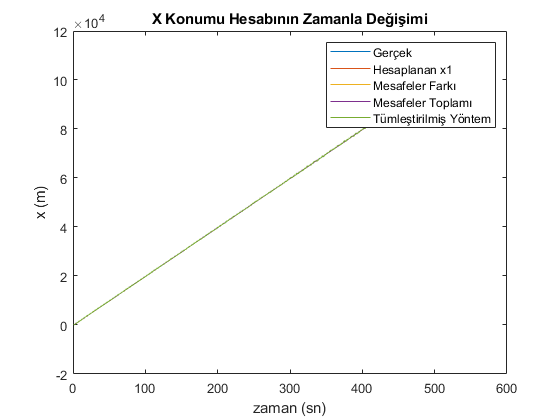

BB=asin(y./D4);
AA=acos(x./(D4.*cos(BB)));

AA = AA + 0.01 * randn(1,501);
BB = BB + 0.01 * randn(1,501);

x4 = DZ4.*cos(BB).*cos(AA);
y4 = DZ4.*sin(BB);
z4 = DZ4.*cos(BB).*sin(AA);

mesafe(4)=sqrt((z4(end)-z4(1))^2 + (x4(end)-x4(1))^2);

figure(3)
hold on
plot(abs(x4))
legend("Gerçek", "Hesaplanan x1", "Mesafeler Farkı", "Mesafeler Toplamı", "Tümleştirilmiş Yöntem");

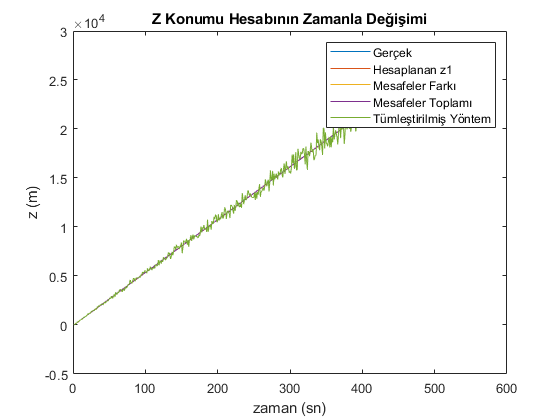



figure(4)
hold on
plot(abs(z4))
legend("Gerçek", "Hesaplanan z1", "Mesafeler Farkı", "Mesafeler Toplamı", "Tümleştirilmiş Yöntem");

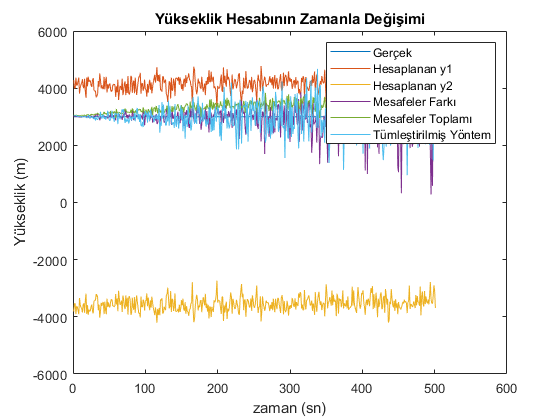



figure(2)
hold on
plot(abs(y4))
legend("Gerçek", "Hesaplanan y1", "Hesaplanan y2", "Mesafeler Farkı", "Mesafeler Toplamı", "Tümleştirilmiş Yöntem")

Orjinden başka konuma alırsak: 1.İstasyon

% BB=asin(y./D1);
% AA=acos(x./(D1.*cos(BB)));
% 
% AA = AA + 0.01 * randn(1,501);
% BB = BB + 0.01 * randn(1,501);
% 
% x4_1 = DZ1.*cos(BB).*cos(AA);
% y4_1 = DZ1.*sin(BB);
% z4_1 = DZ1.*cos(BB).*sin(AA);



2. İstasyon

%BB=asin(y./D2);
%AA=acos(x./(D2.*cos(BB)));

%AA = AA + 0.01 * randn(1,501);
%BB = BB + 0.01 * randn(1,501);

%x4 = DZ2.*cos(BB).*cos(AA);
%y4 = DZ2.*sin(BB);
%z4 = DZ2.*cos(BB).*sin(AA);




3. İstasyon

%BB=asin(y./D3);
%AA=acos(x./(D3.*cos(BB)));

%AA = AA + 0.01 * randn(1,501);
%BB = BB + 0.01 * randn(1,501);

%x4 = DZ3.*cos(BB).*cos(AA);
%y4 = DZ3.*sin(BB);
%z4 = DZ3.*cos(BB).*sin(AA);

%mesafe(4)=sqrt((z4(end)-z4(1))^2 + (x4(end)-x4(1))^2);

